# **Reparameterized Gompertz models with triplicates**

**Loyal Murphy - January 19, 2024**

Using this code, I'll be able to apply the Gompertz model to each system and be able to use the final values.

### **Initialization**

clear variables
clc
clf

# **DATA EXTRACTION**

### Extract Methanotroph Data

scans = dir('*.mat');

all_meth_OD = {};
ms = 0; %Initialize counter

for i = 1:length(scans)
    clear n
    n = scans(i).name;
    if startsWith(n,'M')
        ms = ms + 1;
        meth_data = load(n);
        if length(fieldnames(meth_data)) == 3
            j = fieldnames(meth_data);
            data = meth_data.(j{1});
            factor = meth_data.(j{2});
            to = meth_data.(j{3});
            
            %Get the OD values (multiplying by the factor)
            for x = 1:size(data,1)
                odValues(x) = data{x,1}.Abs(data{x,1}.nm == 600);
            end
            all_meth_OD{ms,1} = reshape(odValues,[size(data,1)/3,3]).*factor';
            if ms == 3
                all_meth_OD{ms,1}(13,2) = 5.46;
            end
            %Get the times
            pts = size(data,1)/3;
            time_matrix = zeros(pts,1); %Initialize time_matrix
            for k = 1:pts
                time_matrix(k) = hours(mean([data{k,2},...
                    data{k+pts,2},...
                    data{k+2*pts,2}]) - to);
            end
            all_meth_OD{ms,2} = time_matrix;

        elseif length(fieldnames(meth_data)) == 2
            j = fieldnames(meth_data);
            
            %Get the OD values (factor already multiplied)
            all_meth_OD{ms,1} = meth_data.(j{1});
            
            %Get the time values (initial time already subtracted)
            all_meth_OD{ms,2} = meth_data.(j{2});
        end

    clear data factor to odValues j k x meth_data pts
    end
end
clear n ms time_matrix i

%Formatting modifications:
all_meth_OD{4,2} = transpose(all_meth_OD{4,2}); %LW14T times
all_meth_OD{6,2} = transpose(all_meth_OD{6,2}); %Quisquiliarum times

### Extract Microalgae Data

scans = dir('*.mat');

all_photo_gDCW = {};
ms = 0; %Initialize counter

for i = 1:length(scans)
    clear n
    n = scans(i).name;
    if startsWith(n,'P')
        ms = ms + 1;
        photo_data = load(n);
        if length(fieldnames(photo_data)) == 3
            j = fieldnames(photo_data);
            data = photo_data.(j{1});
            factor = photo_data.(j{2});
            to = photo_data.(j{3}); 
            
            %Get the OD values (multiplying by the factor)
            for x = 1:size(data,1)
                gDCWValues(x) = data{x,1}.Abs(data{x,1}.nm == 750);
            end
            all_photo_gDCW{ms,1} = reshape(gDCWValues,[size(data,1)/3,3]).*factor';
                            
            %Get the times
            pts = size(data,1)/3;
            time_matrix = zeros(pts,1); %Initialize time_matrix
            for k = 1:pts
                time_matrix(k) = hours(mean([data{k,2},...
                    data{k+pts,2},...
                    data{k+2*pts,2}]) - to);
            end
            all_photo_gDCW{ms,2} = time_matrix;

        elseif length(fieldnames(photo_data)) == 2
            j = fieldnames(photo_data);
            
            %Get the OD values (factor already multiplied)
            all_photo_gDCW{ms,1} = photo_data.(j{1});
            
            %Get the time values (initial time already subtracted)
            all_photo_gDCW{ms,2} = photo_data.(j{2});
        end

    clear data factor to gDCWValues j k x photo_data pts
    end
end
clear n ms time_matrix i 

### Extract Coculture OD Data

scans = dir('*.mat');

all_coc_OD = {};
ms = 0; %Initialize counter

for i = 1:length(scans)
    clear n
    n = scans(i).name;
    if contains(n,'OD') && (startsWith(n,'C') || startsWith(n,'F') || startsWith(n,'L'))
        ms = ms + 1;
        cOD_data = load(n);
        if length(fieldnames(cOD_data)) == 3
            j = fieldnames(cOD_data);
            data = cOD_data.(j{1});
            factor = cOD_data.(j{2});
            to = cOD_data.(j{3});
            
            %Get the OD values (multiplying by the factor)
            for x = 1:size(data,1)
                odValues(x) = data{x,1}.Abs(data{x,1}.nm == 750);
            end
            all_coc_OD{ms,1} = reshape(odValues,[size(data,1)/3,3]).*factor';
                            
            %Get the times
            pts = size(data,1)/3;
            time_matrix = zeros(pts,1); %Initialize time_matrix
            for k = 1:pts
                time_matrix(k) = hours(mean([data{k,2},...
                    data{k+pts,2},...
                    data{k+2*pts,2}]) - to);
            end
            all_coc_OD{ms,2} = time_matrix;

        elseif length(fieldnames(cOD_data)) == 2
            j = fieldnames(cOD_data);
            
            %Get the OD values (factor already multiplied)
            all_coc_OD{ms,1} = cOD_data.(j{1});
            
            %Get the time values (initial time already subtracted)
            all_coc_OD{ms,2} = cOD_data.(j{2});
        end

    clear data factor to odValues j k x cOD_data pts
    end
end
clear n ms time_matrix i

### Extract Coculture gDCW data

scans = dir('*.mat');

all_coc_gDCW = {};
ms = 0; %Initialize counter

for i = 1:length(scans)
    clear n
    n = scans(i).name;
    if contains(n,'gDCW') && (startsWith(n,'C') || startsWith(n,'F') || startsWith(n,'L'))
        ms = ms + 1;
        cDW_data = load(n);
        if length(fieldnames(cDW_data)) == 3
            j = fieldnames(cDW_data);
            data = cDW_data.(j{1});
            factor = cDW_data.(j{2});
            to = cDW_data.(j{3});
            
            %Get the OD values (multiplying by the factor)
            for x = 1:size(data,1)
                gDCWValues(x) = data{x,1}.Abs(data{x,1}.nm == 750);
            end
            all_coc_gDCW{ms,1} = reshape(gDCWValues,[size(data,1)/3,3]).*factor';
            all_coc_gDCW{ms,1} = transpose(all_coc_gDCW{ms,1});
                            
            %Get the times
            pts = size(data,1)/3;
            time_matrix = zeros(pts,1); %Initialize time_matrix
            for k = 1:pts
                time_matrix(k) = hours(mean([data{k,2},...
                    data{k+pts,2},...
                    data{k+2*pts,2}]) - to);
            end
            all_coc_gDCW{ms,2} = time_matrix;
            all_coc_gDCW{ms,2} = transpose(all_coc_gDCW{ms,2})

        elseif length(fieldnames(cDW_data)) == 2
            j = fieldnames(cDW_data);
            
            %Get the OD values (factor already multiplied)
            all_coc_gDCW{ms,1} = cDW_data.(j{1});
            all_coc_gDCW{ms,1} = transpose(all_coc_gDCW{ms,1});
            
            %Get the time values (initial time already subtracted)
            all_coc_gDCW{ms,2} = cDW_data.(j{2});
            all_coc_gDCW{ms,2} = transpose(all_coc_gDCW{ms,2});
        end

    clear data factor to gDCWValues j k x cDW_data pts
    end
end
clear n ms time_matrix i 

%Remove scan data to keep workspace clean
clear scans

# **PLOT GROWTH CURVES and GROWTH RATES**

### Methanotrophs

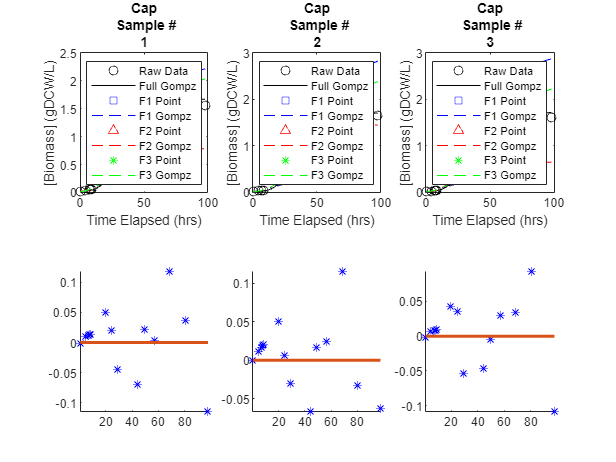

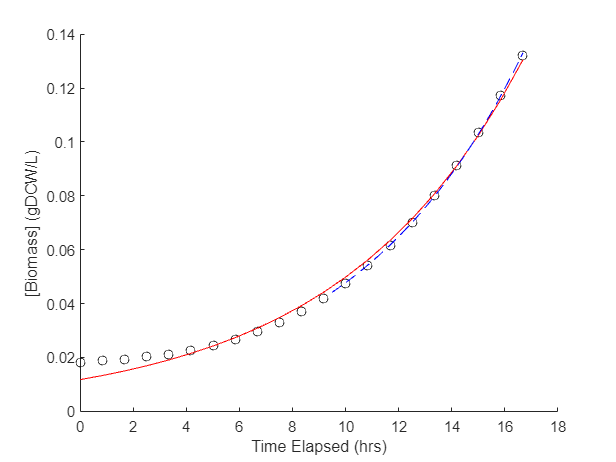

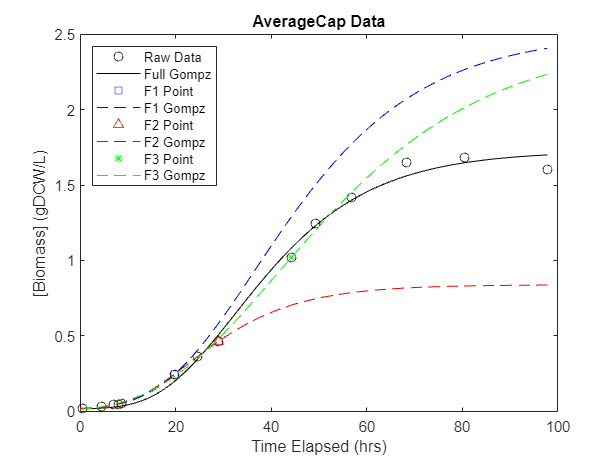

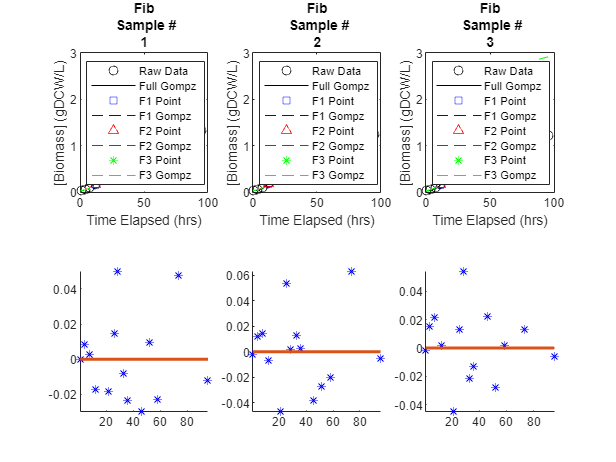

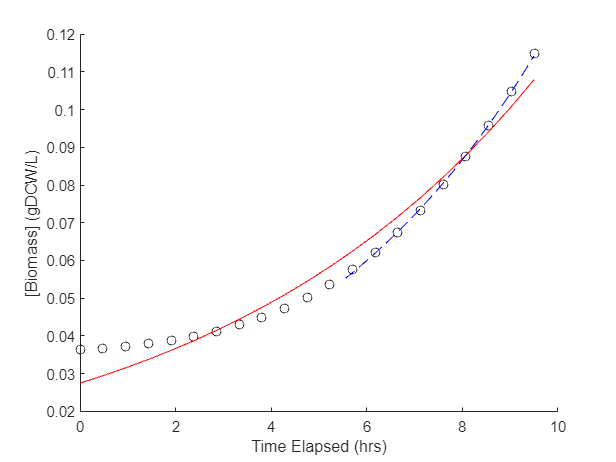

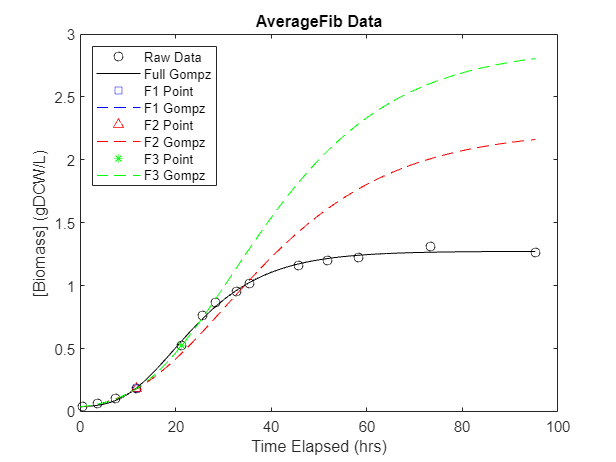

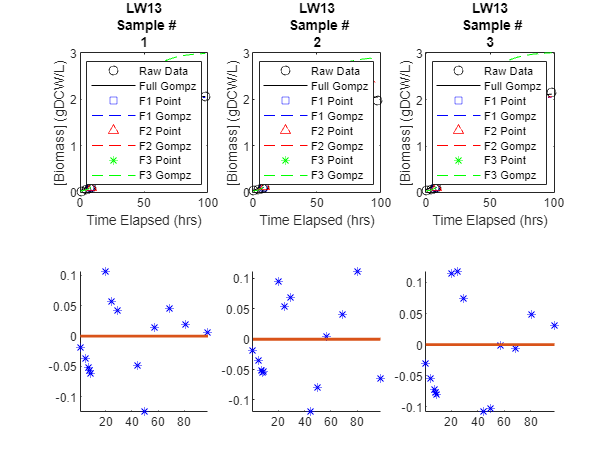

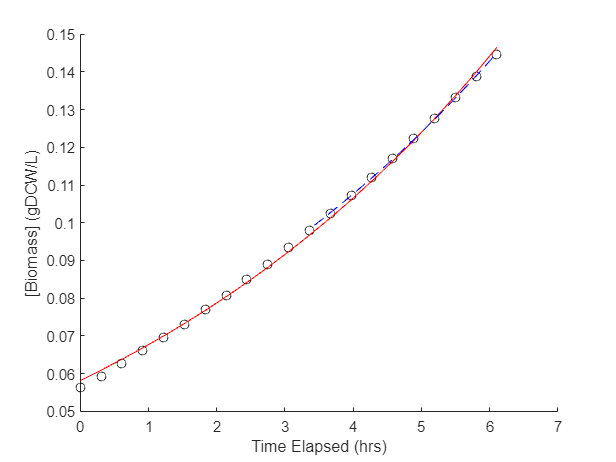

Meth_titles = ["Cap";"Fib";"LW13";"LW14T";"OB3b";"QQ";"S1"];
gDCW_conversion = [0.235,0.369,0.382,0.659,0.460,0.4,0.447];
Colors = {[0.6 0 0],[0 0.5 0.5],[0 0 1],[0.5 0.5 1],[0.4 0.2 0.7],[0 0 0],[0.3 0.3 0]};
Inits = {[1.7,0.1,20],[1.3,0.1,15],[2.1,0.1,15],[0.5,0.1,5],[2.4,0.1,35],[1,0.01,50],[0.8,0.1,10]}; %Initials for ZM solver
Inits2 = {[0.15,1],[0.15,1],[0.15,1],[0.15,1],[0.10,10],[0.05,1],[0.15,1]}; %Initials for XM solver
% Make storage variables for later %
K_vals = zeros(3,length(Meth_titles));
muR_vals = zeros(3,length(Meth_titles));
tLAG_vals = zeros(3,length(Meth_titles));
mu_max_vals = zeros(3,length(Meth_titles));
mu_max_vals3 = zeros(3,length(Meth_titles));
td_vals = zeros(3,length(Meth_titles));
D_vals = zeros(3,length(Meth_titles));

for i = 1:size(all_meth_OD,1)
    ODs = all_meth_OD{i,1};
    gDCWs = ODs*gDCW_conversion(i);
    Times = all_meth_OD{i,2};    

    % Plot the individual data sets with their Gompertz models
    x = Times;
    figure(); clf;
    for j = 1:3
        % Set up fitting parameters %
        Xo = gDCWs(1,j); %Initial biomass
        foB = fitoptions('Method','NonlinearLeastSquares','Lower',[0,0,0,0],'Upper',[3,0.35,100,Xo],'StartPoint',[Inits{i},Xo]);
        ft_ZMB = fittype('d + a*exp(-exp(exp(1)*b/a * (c - x) + 1))','independent',{'x'},'dependent',{'y'},'options',foB); %Zweitering
        % a = Carrying Capacity
        % b = Growth Rate
        % c = Lag Time
        % d = Vertical Shift

        % Gompertz Model Predictions %
        y = gDCWs(:,j);
        [curve_ZMB,sZMB] = fit(x,y,ft_ZMB);
        subplot(2,3,j)
        plot(x,y,'ko',linspace(0,max(x),301),curve_ZMB(linspace(0,max(x),301)),'k-')
        xlabel('Time Elapsed (hrs)')
        ylabel('[Biomass] (gDCW/L)')
        title([Meth_titles(i),' Sample #',num2str(j)])
        K_vals(j,i) = curve_ZMB.a;
        muR_vals(j,i) = curve_ZMB.b;
        tLAG_vals(j,i) = curve_ZMB.c;
        D_vals(j,i) = curve_ZMB.d;

        % Can you get roughly the same plots if you know Tlag? %
        % Try different time frames! (F1, F2, F3) %
        F1 = length(x(x<tLAG_vals(j,i))) + 1; %Use up to point after Tlag
        if F1 < 4
            F1 = 4; %Allows the model to work
        end
        F2 = length(x(x<(2*tLAG_vals(j,i)))); %Use points within 2*Tlag
        if F2 < 4
            F2 = 4; %Allows the model to work
        end
        F3 = length(x(x<(2*tLAG_vals(j,i)))) + 1; %Use up to point after 2*Tlag
        if F3 < 4
            F3 = 4; %Allows model to work
        end
        [curve_F1,~] = fit(x(1:F1),y(1:F1),ft_ZMB);
        [curve_F2,~] = fit(x(1:F2),y(1:F2),ft_ZMB);
        [curve_F3,~] = fit(x(1:F3),y(1:F3),ft_ZMB);
        hold on
        plot(x(F1),y(F1),'bs',linspace(0,max(x),301),curve_F1(linspace(0,max(x),301)),'b--');
        plot(x(F2),y(F2),'r^',linspace(0,max(x),301),curve_F2(linspace(0,max(x),301)),'r--');
        plot(x(F3),y(F3),'g*',linspace(0,max(x),301),curve_F3(linspace(0,max(x),301)),'g--');
        hold off
        legend('Raw Data','Full Gompz','F1 Point','F1 Gompz','F2 Point','F2 Gompz','F3 Point','F3 Gompz',...
            'location','northwest')

        subplot(2,3,j+3)
        hold on
        plot(Times,y-curve_ZMB(Times),'b*')
        line([Times(1),Times(end)],[0,0],'LineWidth',2)
        axis tight
        hold off

        % Exponential Predictions from full Gompertz %
        tEXP = linspace(0,tLAG_vals(j,i),21); %21 points between start and Tlag
        %fo2 = fitoptions('Method','NonlinearLeastSquares','Lower',[0,0],'Upper',[0.3,30],'StartPoint',Inits2{i});
        %ft_XM = fittype('Xo*exp(a*(t-b))','independent',{'t'},'dependent',{'y'},'problem',{'Xo'},'options',fo2); %Exponential Growth
        fo2 = fitoptions('Method','NonlinearLeastSquares','Lower',[0,0,0],'Upper',[Xo*5,0.3,30],'StartPoint',[Xo,Inits2{i}]);
        ft_XMXo = fittype('Xo*exp(a*(t-b))','independent',{'t'},'dependent',{'y'},'options',fo2); %Exponential Growth
        [curve_XMXo,sXMXo] = fit(tEXP',curve_ZMB(tEXP),ft_XMXo);
        %disp(strcat(Meth_titles(i) , ' Sample # ' , num2str(j) ,' has XMXo R^2 of ', num2str(sXMXo.adjrsquare)));
        mu_max_vals(j,i) = curve_XMXo.a;
        td_vals(j,i) = curve_XMXo.b;     

        % t_d values are reasonable, but the mu_max vals are off %
        % Try using time between t_d and Tlag to get mu_max %
        tEXP3 = linspace(mean([td_vals(j,i),tLAG_vals(j,i)]),tLAG_vals(j,i),21);
        fo3 = fitoptions('Method','NonlinearLeastSquares','Lower',[0,0,0],'Upper',[Xo*2,0.3,30],'StartPoint',[Xo,Inits2{i}]);
        ft_XMXo3 = fittype('Xo*exp(a*(t-b))','independent',{'t'},'dependent',{'y'},'options',fo3); %Exponential Growth
        [curve_XMXo3,sXMXo3] = fit(tEXP3',curve_ZMB(tEXP3),ft_XMXo3);
        %disp(strcat(Meth_titles(i) , ' Sample # ' , num2str(j) ,' has XMXo3 R^2 of ', num2str(sXMXo3.adjrsquare)));
        mu_max_vals3(j,i) = curve_XMXo3.a;
    end

figure(); clf;
hold on
plot(tEXP,curve_ZMB(tEXP),'ko');
plot(tEXP,curve_XMXo(tEXP),'r-');
plot(tEXP3,curve_XMXo3(tEXP3),'b--');
xlabel('Time Elapsed (hrs)');
ylabel('[Biomass] (gDCW/L)');
hold off

figure(); clf;
y2 = mean(gDCWs,2);
[curve_Ave,sAve] = fit(x,y2,ft_ZMB);
plot(x,y2,'ko',linspace(0,max(x),301),curve_Ave(linspace(0,max(x),301)),'k-');
xlabel('Time Elapsed (hrs)');
ylabel('[Biomass] (gDCW/L)');
title(strcat('Average ',Meth_titles(i),' Data'));

F1 = length(x(x<mean(tLAG_vals(:,i)))) + 1; %Use up to point after Tlag
if F1 < 4
    F1 = 4; %Allows the model to work
end
F2 = length(x(x<(2*mean(tLAG_vals(:,i))))); %Use points within 2*Tlag
if F2 < 4
    F2 = 4; %Allows the model to work
end
F3 = length(x(x<(2*mean(tLAG_vals(:,i))))) + 1; %Use up to point after 2*Tlag
if F3 < 4
    F3 = 4; %Allows model to work
end

[curve_F1,sF1] = fit(x(1:F1),y2(1:F1),ft_ZMB);
[curve_F2,sF2] = fit(x(1:F2),y2(1:F2),ft_ZMB);
[curve_F3,sF3] = fit(x(1:F3),y2(1:F3),ft_ZMB);
hold on
plot(x(F1),y2(F1),'bs',linspace(0,max(x),301),curve_F1(linspace(0,max(x),301)),'b--');
plot(x(F2),y2(F2),'r^',linspace(0,max(x),301),curve_F2(linspace(0,max(x),301)),'r--');
plot(x(F3),y2(F3),'g*',linspace(0,max(x),301),curve_F3(linspace(0,max(x),301)),'g--');
hold off
legend('Raw Data','Full Gompz','F1 Point','F1 Gompz','F2 Point','F2 Gompz','F3 Point','F3 Gompz',...
            'location','northwest')

end

## **Plotting Methanotroph Monoculture Data**

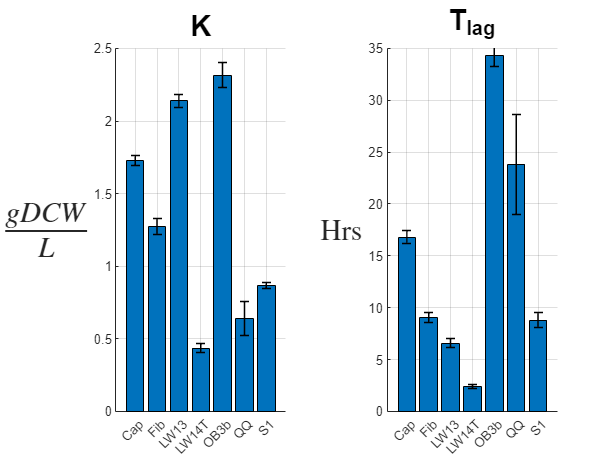

figure(); clf;
subplot(1,2,1)
hold on
b = bar(categorical(Meth_titles),mean(K_vals) + mean(D_vals));
errorbar(mean(K_vals + mean(D_vals)),std(K_vals),'LineStyle','none','Color','k','LineWidth',1);
hold off
ylabel('$\frac{gDCW}{L}$','Interpreter','latex','FontSize',20,'FontWeight','bold','Rotation',0);
ylim([0,2.5]);
title('K','FontSize',20,'FontWeight','bold');
grid on

subplot(1,2,2)
hold on
b = bar(categorical(Meth_titles),mean(tLAG_vals));
errorbar(mean(tLAG_vals),std(tLAG_vals),'LineStyle','none','Color','k','LineWidth',1);
hold off
ylabel('Hrs','Interpreter','latex','FontSize',20,'FontWeight','bold','Rotation',0);
ylim([0,35]);
title('T_{lag}','FontSize',20,'FontWeight','bold');
grid on

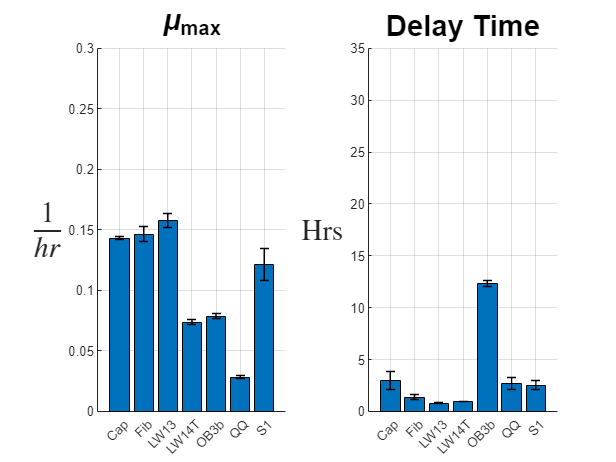


figure(); clf;
subplot(1,2,1)
hold on
b = bar(categorical(Meth_titles),mean(mu_max_vals));
errorbar(mean(mu_max_vals),std(mu_max_vals),'LineStyle','none','Color','k','LineWidth',1);
hold off
title('\mu_{max}','FontSize',20,'FontWeight','bold')
ylabel('$\frac{1}{hr}$','Interpreter','latex','FontSize',20,'FontWeight','bold','Rotation',0);
ylim([0,0.3]);
grid on

subplot(1,2,2)
hold on
b = bar(categorical(Meth_titles),mean(td_vals));
errorbar(mean(td_vals),std(td_vals),'LineStyle','none','Color','k','LineWidth',1);
hold off
title('Delay Time','FontSize',20,'FontWeight','bold')
ylabel('Hrs','Interpreter','latex','FontSize',20,'FontWeight','bold','Rotation',0);
ylim([0,35]);
grid on

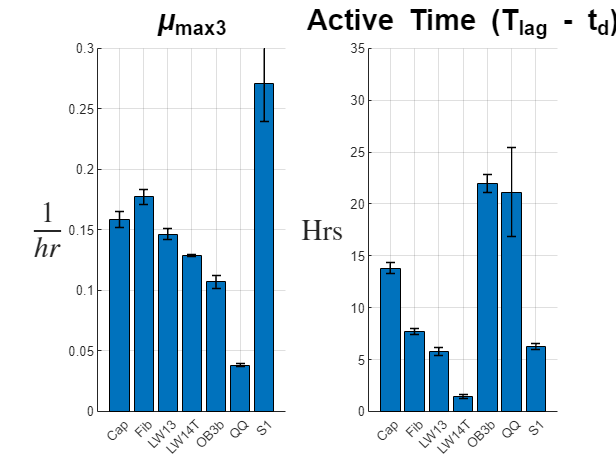



figure(); clf;
subplot(1,2,1)
hold on
b = bar(categorical(Meth_titles),mean(mu_max_vals3));
errorbar(mean(mu_max_vals3),std(mu_max_vals3),'LineStyle','none','Color','k','LineWidth',1);
hold off
title('\mu_{max3}','FontSize',20,'FontWeight','bold')
ylabel('$\frac{1}{hr}$','Interpreter','latex','FontSize',20,'FontWeight','bold','Rotation',0);
ylim([0,0.3]);
grid on

% Tlag - td shows time actively growing on AD %
subplot(1,2,2)
activeT = tLAG_vals - td_vals;
hold on
b = bar(categorical(Meth_titles),mean(activeT));
errorbar(mean(activeT),std(activeT),'LineStyle','none','Color','k','LineWidth',1);
hold off
title('Active Time (T_{lag} - t_{d})','FontSize',20,'FontWeight','bold')
ylabel('Hrs','Interpreter','latex','FontSize',20,'FontWeight','bold','Rotation',0);
ylim([0,35]);
grid on

## Microalgae Monoculture Data

Dim Sample #1 has XMXo R^2 of0.99468


Dim Sample #1 has XMXo3 R^2 of0.99945


Dim Sample #2 has XMXo R^2 of0.9944


Dim Sample #2 has XMXo3 R^2 of0.9994


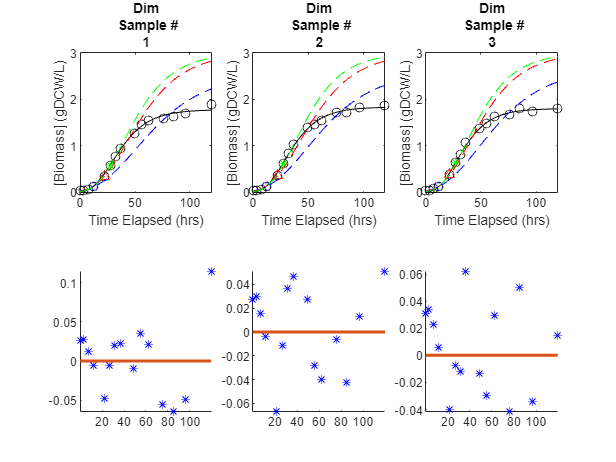

Dim Sample #3 has XMXo R^2 of0.99405


Dim Sample #3 has XMXo3 R^2 of0.99947


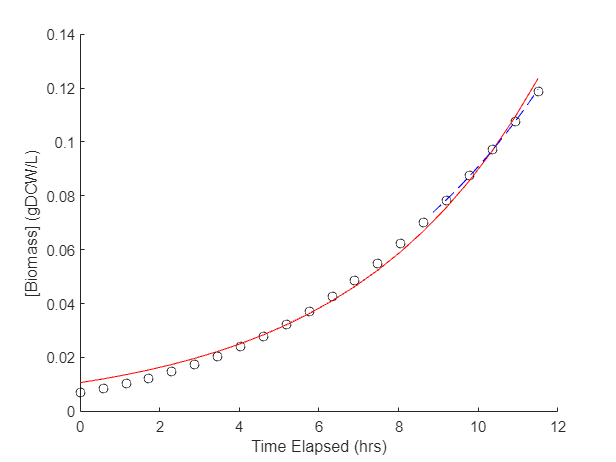

Kess Sample #1 has XMXo R^2 of0.99369


Kess Sample #1 has XMXo3 R^2 of0.99742


Kess Sample #2 has XMXo R^2 of0.99333


Kess Sample #2 has XMXo3 R^2 of0.99757


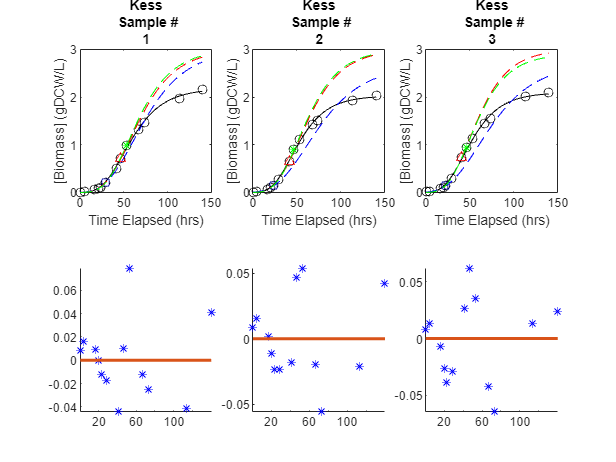

Kess Sample #3 has XMXo R^2 of0.99335


Kess Sample #3 has XMXo3 R^2 of0.99777


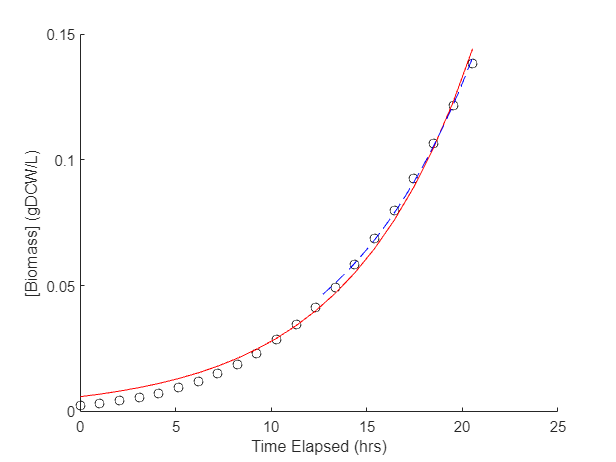

Obli Sample #1 has XMXo R^2 of0.99333


Obli Sample #1 has XMXo3 R^2 of0.99864


Obli Sample #2 has XMXo R^2 of0.99341


Obli Sample #2 has XMXo3 R^2 of0.99844


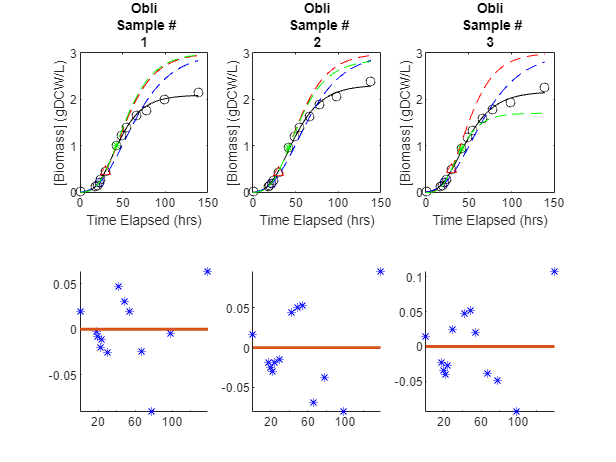

Obli Sample #3 has XMXo R^2 of0.99373


Obli Sample #3 has XMXo3 R^2 of0.99859


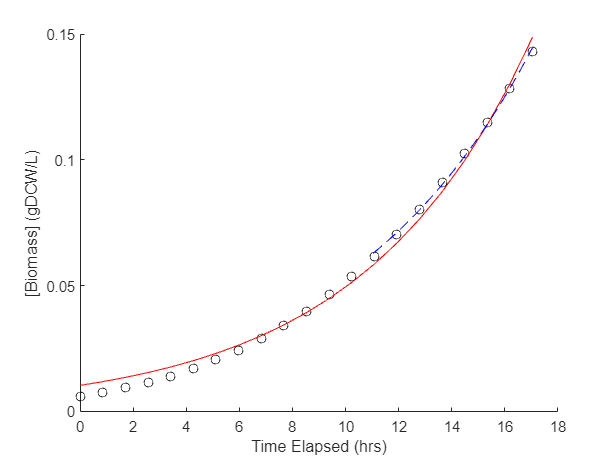

Soro Sample #1 has XMXo R^2 of0.99419


Soro Sample #1 has XMXo3 R^2 of0.99931


Soro Sample #2 has XMXo R^2 of0.99462


Soro Sample #2 has XMXo3 R^2 of0.99939


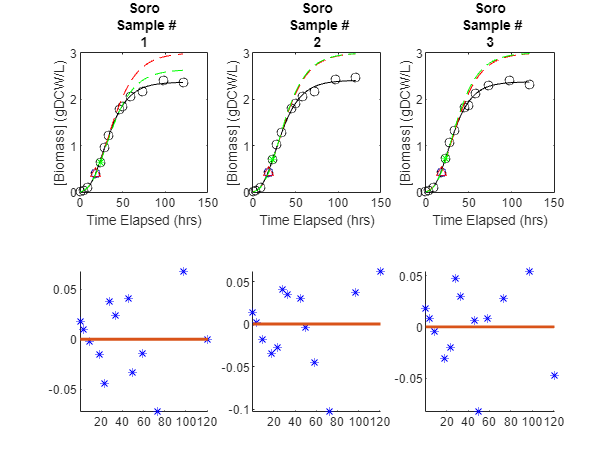

Soro Sample #3 has XMXo R^2 of0.99422


Soro Sample #3 has XMXo3 R^2 of0.99936


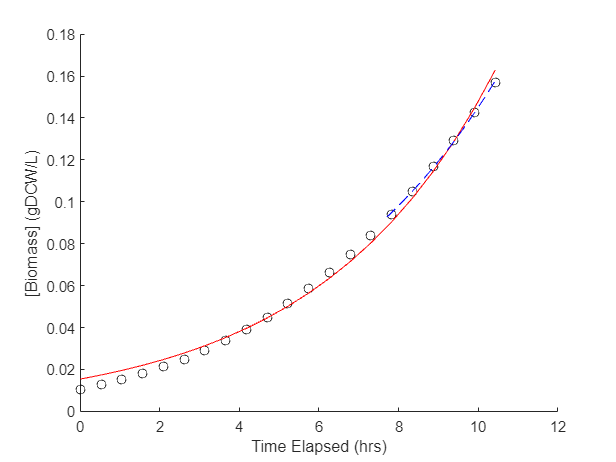

Vulg Sample #1 has XMXo R^2 of0.9942


Vulg Sample #1 has XMXo3 R^2 of0.99843


Vulg Sample #2 has XMXo R^2 of0.99445


Vulg Sample #2 has XMXo3 R^2 of0.99837


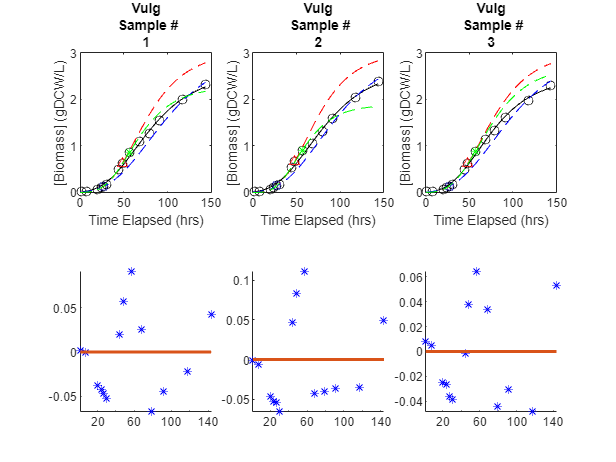

Vulg Sample #3 has XMXo R^2 of0.99375


Vulg Sample #3 has XMXo3 R^2 of0.99816


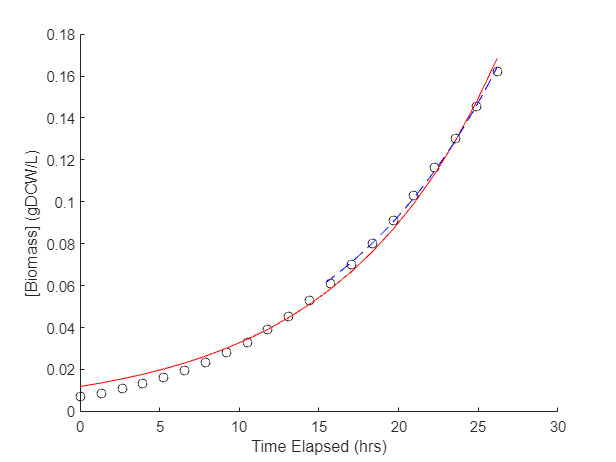

Photo_titles = ["Dim";"Kess";"Obli";"Soro";"Vulg"];
Colors = {[0.6 0 0],[0 0.5 0.5],[0 0 1],[0.5 0.5 1],[0.4 0.2 0.7]};
gDCW_conversion = [0.52,1,1,0.39,1]; %Dimorphus and Sorokiniana data are OD's!
Inits = {[1.7,0.1,0],[2.2,0.05,2],[2.3,0.1,2],[2.4,0.1,2],[3,0.05,10]}; %Initials for solver!
Inits2 = {[0.15,5],[0.15,5],[0.15,5],[0.15,5],[0.15,5]};

% Make storage variables for later %
K_vals = zeros(3,length(Photo_titles));
D_vals = zeros(3,length(Photo_titles));
muR_vals = zeros(3,length(Photo_titles));
tLAG_vals = zeros(3,length(Photo_titles));
mu_max_vals = zeros(3,length(Photo_titles));
mu_max_vals3 = zeros(3,length(Photo_titles));
td_vals = zeros(3,length(Photo_titles));

for i = 1:size(all_photo_gDCW,1)
    raws = all_photo_gDCW{i,1};
    gDCWs = raws*gDCW_conversion(i);
    Times = all_photo_gDCW{i,2};
    
    % Plot the individual data sets with their Gompertz models
    x = Times;
    figure(); clf;
    for j = 1:3
        % Set up fitting parameters %
        Xo = gDCWs(1,j); %Initial biomass
        foB = fitoptions('Method','NonlinearLeastSquares','Lower',[0,0,0,0],'Upper',[3,0.35,100,0],'StartPoint',[Inits{i},0]);
        ft_ZMB = fittype('d + a*exp(-exp(exp(1)*b/a * (c - x) + 1))','independent',{'x'},'dependent',{'y'},'options',foB); %Zweitering
        % a = Carrying Capacity
        % b = Growth Rate
        % c = Delay Time
        % d = Vertical Shift

        % Define gDCW measurements and model predictions
        y = gDCWs(:,j);
        [curve_ZMB,sZMB] = fit(x,y,ft_ZMB);
        subplot(2,3,j)
        plot(x,y,'ko',linspace(0,max(x),301),curve_ZMB(linspace(0,max(x),301)),'k-')
        xlabel('Time Elapsed (hrs)')
        ylabel('[Biomass] (gDCW/L)')
        title([Photo_titles(i),' Sample #',num2str(j)])
        K_vals(j,i) = curve_ZMB.a;
        muR_vals(j,i) = curve_ZMB.b;
        tLAG_vals(j,i) = curve_ZMB.c;
        D_vals(j,i) = curve_ZMB.d;

        % Can you get roughly the same plots if you know Tlag? %
        % Try different time frames! (F1, F2, F3) %
        F1 = length(x(x<tLAG_vals(j,i))) + 1; %Use up to point after Tlag
        if F1 < 4
            F1 = 4; %Allows the model to work
        end
        F2 = length(x(x<(2*tLAG_vals(j,i)))); %Use points within 2*Tlag
        if F2 < 4
            F2 = 4; %Allows the model to work
        end
        F3 = length(x(x<(2*tLAG_vals(j,i)))) + 1; %Use up to point after 2*Tlag
        if F3 < 4
            F3 = 4; %Allows model to work
        end
        [curve_F1,sF1] = fit(x(1:F1),y(1:F1),ft_ZMB);
        [curve_F2,sF2] = fit(x(1:F2),y(1:F2),ft_ZMB);
        [curve_F3,sF3] = fit(x(1:F3),y(1:F3),ft_ZMB);
        hold on
        plot(x(F1),y(F1),'bs',linspace(0,max(x),301),curve_F1(linspace(0,max(x),301)),'b--');
        plot(x(F2),y(F2),'r^',linspace(0,max(x),301),curve_F2(linspace(0,max(x),301)),'r--');
        plot(x(F3),y(F3),'g*',linspace(0,max(x),301),curve_F3(linspace(0,max(x),301)),'g--');
        hold off

        subplot(2,3,j+3)
        hold on
        plot(Times,y-curve_ZMB(Times),'b*')
        line([Times(1),Times(end)],[0,0],'LineWidth',2)
        axis tight
        hold off

        % Exponential Predictions from full Gompertz %
        tEXP = linspace(0,tLAG_vals(j,i),21); %21 points between start and Tlag
        % tEXP = Times(1:3); %First three points
        % fo2 = fitoptions('Method','NonlinearLeastSquares','Lower',[0,0],'Upper',[0.3,30],'StartPoint',Inits2{i});
        % ft_XM = fittype('Xo*exp(a*(t-b))','independent',{'t'},'dependent',{'y'},'problem',{'Xo'},'options',fo2); %Exponential Growth
        % [curve_XM,sXM] = fit(tEXP',curve_ZMB(tEXP),ft_XM,'problem',Xo);
        % [curve_XM,sXM] = fit(tEXP,y(1:3),ft_XM,'problem',Xo);
        fo2 = fitoptions('Method','NonlinearLeastSquares','Lower',[Xo,0,0],'Upper',[Xo*5,0.3,30],'StartPoint',[Xo,Inits2{i}]);
        ft_XMXo = fittype('Xo*exp(a*(t-b))','independent',{'t'},'dependent',{'y'},'options',fo2); %Exponential Growth
        [curve_XMXo,sXMXo] = fit(tEXP',curve_ZMB(tEXP),ft_XMXo);
        mu_max_vals(j,i) = curve_XMXo.a;
        td_vals(j,i) = curve_XMXo.b; 
        disp(strcat(Photo_titles(i) , ' Sample # ' , num2str(j) ,' has XMXo R^2 of ', num2str(sXMXo.adjrsquare)));

        % t_d values are reasonable, but the mu_max vals are off %
        % Try using time between t_d and Tlag to get mu_max %
        tEXP3 = linspace(mean([td_vals(j,i),tLAG_vals(j,i)]),tLAG_vals(j,i),21);
        fo3 = fitoptions('Method','NonlinearLeastSquares','Lower',[0,0,0],'Upper',[Xo*5,0.3,30],'StartPoint',[Xo,Inits2{i}]);
        ft_XMXo3 = fittype('Xo*exp(a*(t-b))','independent',{'t'},'dependent',{'y'},'options',fo3); %Exponential Growth
        [curve_XMXo3,sXMXo3] = fit(tEXP3',curve_ZMB(tEXP3),ft_XMXo3);
        disp(strcat(Photo_titles(i) , ' Sample # ' , num2str(j) ,' has XMXo3 R^2 of ', num2str(sXMXo3.adjrsquare)));
        mu_max_vals3(j,i) = curve_XMXo3.a;
    end

figure(); clf;
hold on
plot(tEXP,curve_ZMB(tEXP),'ko');
plot(tEXP,curve_XMXo(tEXP),'r-');
plot(tEXP3,curve_XMXo3(tEXP3),'b--');
xlabel('Time Elapsed (hrs)');
ylabel('[Biomass] (gDCW/L)');
hold off

end

## **Plotting Microalgae Monoculture Data**

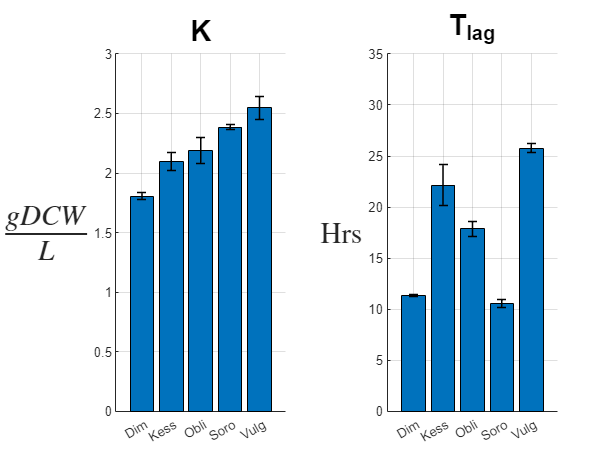

figure(); clf;
subplot(1,2,1)
hold on
b = bar(categorical(Photo_titles),mean(K_vals)+mean(D_vals));
errorbar(mean(K_vals) + mean(D_vals),std(K_vals),'LineStyle','none','Color','k','LineWidth',1);
hold off
ylabel('$\frac{gDCW}{L}$','Interpreter','latex','FontSize',20,'FontWeight','bold','Rotation',0);
ylim([0,3]);
title('K','FontSize',20,'FontWeight','bold');
grid on

subplot(1,2,2)
hold on
bar(categorical(Photo_titles),mean(tLAG_vals));
errorbar(mean(tLAG_vals),std(tLAG_vals),'LineStyle','none','Color','k','LineWidth',1);
hold off
ylabel('Hrs','Interpreter','latex','FontSize',20,'FontWeight','bold','Rotation',0);
ylim([0,35]);
title('T_{lag}','FontSize',20,'FontWeight','bold');
grid on

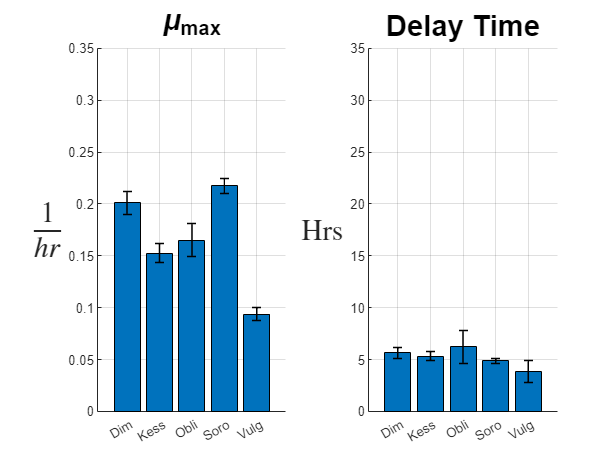


figure(); clf;
subplot(1,2,1)
hold on
b = bar(categorical(Photo_titles),mean(mu_max_vals));
errorbar(mean(mu_max_vals),std(mu_max_vals),'LineStyle','none','Color','k','LineWidth',1);
hold off
title('\mu_{max}','FontSize',20,'FontWeight','bold')
ylabel('$\frac{1}{hr}$','Interpreter','latex','FontSize',20,'FontWeight','bold','Rotation',0);
ylim([0,0.35]);
grid on

subplot(1,2,2)
hold on
b = bar(categorical(Photo_titles),mean(td_vals));
errorbar(mean(td_vals),std(td_vals),'LineStyle','none','Color','k','LineWidth',1);
hold off
title('Delay Time','FontSize',20,'FontWeight','bold')
ylabel('Hrs','Interpreter','latex','FontSize',20,'FontWeight','bold','Rotation',0);
ylim([0,35]);
grid on


figure(); clf;
subplot(1,2,1)
hold on
b = bar(categorical(Photo_titles),mean(mu_max_vals3));
errorbar(mean(mu_max_vals3),std(mu_max_vals3),'LineStyle','none','Color','k','LineWidth',1);
hold off
title('\mu_{max3}','FontSize',20,'FontWeight','bold')
ylabel('$\frac{1}{hr}$','Interpreter','latex','FontSize',20,'FontWeight','bold','Rotation',0);
ylim([0,0.3]);
grid on

disp(mean(mu_max_vals3));

    0.1732    0.1385    0.1464    0.1882    0.0848



disp(std(mu_max_vals3));

    0.0086    0.0081    0.0124    0.0061    0.0057



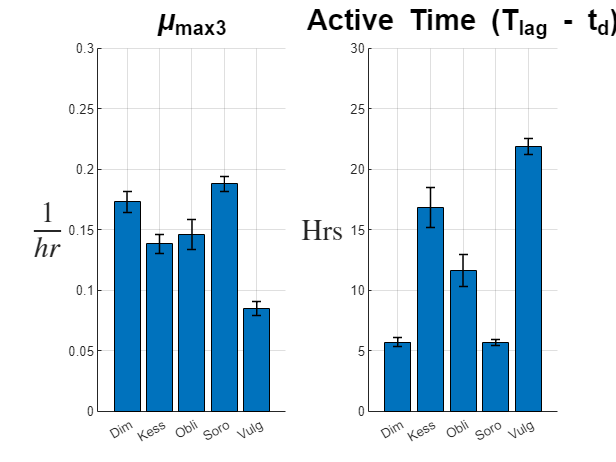


% Tlag - td shows time actively growing on AD %
subplot(1,2,2)
activeT = tLAG_vals - td_vals;
hold on
b = bar(categorical(Photo_titles),mean(activeT));
errorbar(mean(activeT),std(activeT),'LineStyle','none','Color','k','LineWidth',1);
hold off
title('Active Time (T_{lag} - t_{d})','FontSize',20,'FontWeight','bold')
ylabel('Hrs','Interpreter','latex','FontSize',20,'FontWeight','bold','Rotation',0);
ylim([0,30]);
grid on

### Cocultures OD Data

Cap + Dim Sample #1 has XMXo R^2 of0.99802


Cap + Dim Sample #1 has XMXo3 R^2 of0.99954


Cap + Dim Sample #2 has XMXo R^2 of0.99719


Cap + Dim Sample #2 has XMXo3 R^2 of0.9993


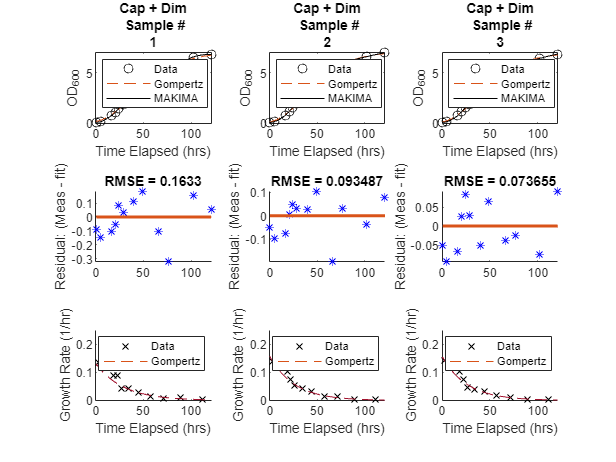

Cap + Dim Sample #3 has XMXo R^2 of0.99726


Cap + Dim Sample #3 has XMXo3 R^2 of0.99931


Cap + Soro Sample #1 has XMXo R^2 of0.99819


Cap + Soro Sample #1 has XMXo3 R^2 of0.99975


Cap + Soro Sample #2 has XMXo R^2 of0.99787


Cap + Soro Sample #2 has XMXo3 R^2 of0.99974


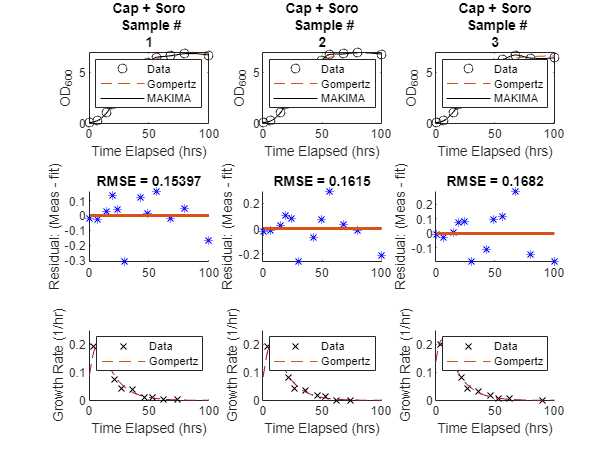

Cap + Soro Sample #3 has XMXo R^2 of0.99951


Cap + Soro Sample #3 has XMXo3 R^2 of0.99952


Fib + Dim Sample #1 has XMXo R^2 of0.91122


Fib + Dim Sample #1 has XMXo3 R^2 of0.99991


Fib + Dim Sample #2 has XMXo R^2 of0.91949


Fib + Dim Sample #2 has XMXo3 R^2 of0.99994


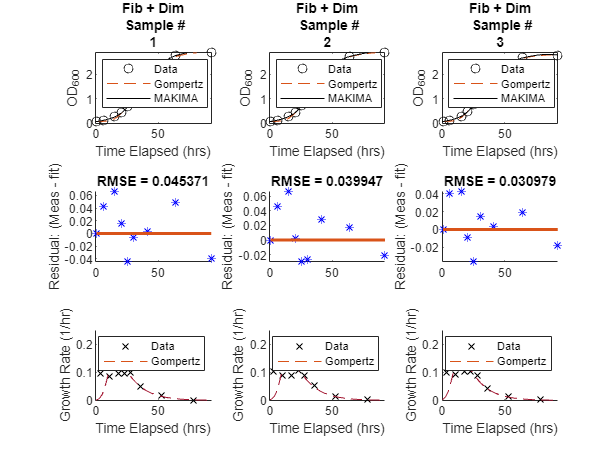

Fib + Dim Sample #3 has XMXo R^2 of0.92808


Fib + Dim Sample #3 has XMXo3 R^2 of0.99996


Fib + Soro Sample #1 has XMXo R^2 of0.99425


Fib + Soro Sample #1 has XMXo3 R^2 of0.99897


Fib + Soro Sample #2 has XMXo R^2 of0.99452


Fib + Soro Sample #2 has XMXo3 R^2 of0.99896


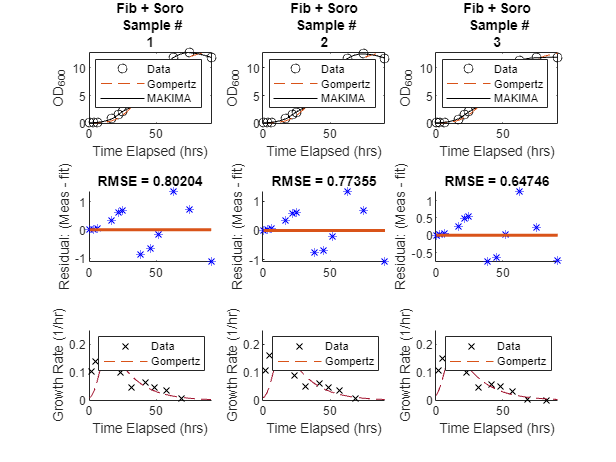

Fib + Soro Sample #3 has XMXo R^2 of0.99627


Fib + Soro Sample #3 has XMXo3 R^2 of0.999


LW13 + Dim Sample #1 has XMXo R^2 of0.79419


LW13 + Dim Sample #1 has XMXo3 R^2 of0.99975


LW13 + Dim Sample #2 has XMXo R^2 of0.91199


LW13 + Dim Sample #2 has XMXo3 R^2 of0.99998


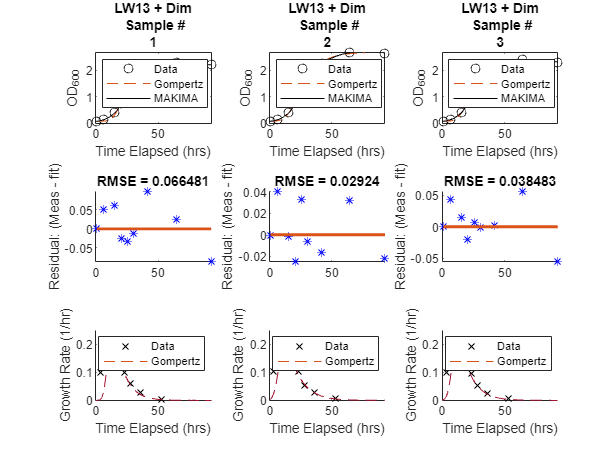

LW13 + Dim Sample #3 has XMXo R^2 of0.87434


LW13 + Dim Sample #3 has XMXo3 R^2 of0.99994


LW13 + Soro Sample #1 has XMXo R^2 of0.9951


LW13 + Soro Sample #1 has XMXo3 R^2 of0.9991


LW13 + Soro Sample #2 has XMXo R^2 of0.996


LW13 + Soro Sample #2 has XMXo3 R^2 of0.99927


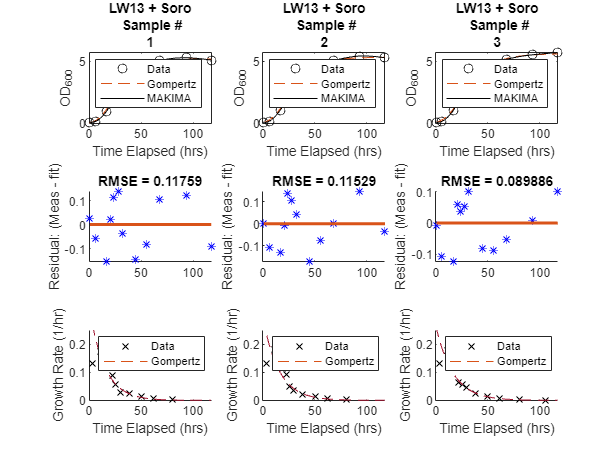

LW13 + Soro Sample #3 has XMXo R^2 of0.99616


LW13 + Soro Sample #3 has XMXo3 R^2 of0.99923


Coc_titles = ["Cap + Dim";"Cap + Soro";"Fib + Dim";"Fib + Soro";"LW13 + Dim";"LW13 + Soro"];
Colors = {'k','k','r','r','b','b'};
Styles = {'-','--','-','--','-','--'};
Inits = {[7,0.1,2],[6.5,0.1,2],[3,0.1,20],[12,0.1,1],[2.5,0.1,1],[5.5,0.1,1]}; %Initials for solver!
Inits2 = {[0.1,1],[0.15,1],[0.10,10],[0.15,1],[0.1,10],[0.15,1]}; %Initials for exponential solver

% Make storage variables for later %
K_vals = zeros(3,length(Coc_titles));
D_vals = zeros(3,length(Coc_titles));
muR_vals = zeros(3,length(Coc_titles));
tLAG_vals = zeros(3,length(Coc_titles));
mu_max_vals = zeros(3,length(Coc_titles));
mu_max_vals3 = zeros(3,length(Coc_titles));
td_vals = zeros(3,length(Coc_titles));
rmse_vals = zeros(3,length(Coc_titles));
nrmse_vals = zeros(3,length(Coc_titles));


for i = 1:size(all_coc_OD,1)
    ODs = all_coc_OD{i,1};
    Times = all_coc_OD{i,2};

    % Plot the individual data sets with their Gompertz models
    x = Times;
    if i == 4
        x = x'; % Only this series is a row instead of column %
    end
    figure(); clf;
    for j = 1:3
        % Set up fitting parameters %
        Xo = ODs(1,j); %Initial biomass
        foB = fitoptions('Method','NonlinearLeastSquares','Lower',[0,0,0,0],'Upper',[15,0.3,25,Xo],'StartPoint',[Inits{i},Xo]);
        ft_ZMB = fittype('d + a*exp(-exp(exp(1)*b/a * (c - x) + 1))','independent',{'x'},'dependent',{'y'},'options',foB); %Zweitering
        % a = Carrying Capacity
        % b = Growth Rate
        % c = Delay Time
        % d = Vertical Shift

        % Gompertz and MAKIMA fits
        y = ODs(:,j);
        xq = linspace(0,max(x),301);
        [curve_ZMB,sZMB] = fit(x,y,ft_ZMB);
        mak_y = makima(x,y,xq);
        subplot(3,3,j)
        plot(x,y,'ko',xq,curve_ZMB(xq),'--',xq,mak_y,'k-')
        xlabel('Time Elapsed (hrs)')
        ylabel('OD_{600}')
        title([Coc_titles(i),' Sample #',num2str(j)])
        legend('Data','Gompertz','MAKIMA','location','northwest')
        axis([0,max(x),0,max(ODs,[],'all')])
        K_vals(j,i) = curve_ZMB.a;
        muR_vals(j,i) = curve_ZMB.b;
        tLAG_vals(j,i) = curve_ZMB.c;
        D_vals(j,i) = curve_ZMB.d;
        rmse_vals(j,i) = sZMB.rmse;
        nrmse_vals(j,i) = rmse_vals(j,i)*100/(max(y)-min(y));


        subplot(3,3,j+3)
        hold on
        plot(Times,y-curve_ZMB(Times),'b*')
        line([Times(1),Times(end)],[0,0],'LineWidth',2)
        ylabel('Residual: (Meas - fit)')
        axis tight
        xlim([0,max(x)])
        hold off
        title(['RMSE = ',num2str(rmse_vals(j,i))])
        % res = y - curve_ZMB(Times);
        % DW_Test = sum((res(2:end)-res(1:end-1)).^2)/sum(res.^2);
        % autocorr(res)
        % xlabel('# of Lags')
        % ylim([-1 1])
        % title(['Durbin-Watson = ',num2str(DW_Test)])


        subplot(3,3,j+6)
        mu_data = log(y(2:end)./y(1:end-1))./(x(2:end)-x(1:end-1));
        mu_gomp = log(curve_ZMB(xq(2:end))./curve_ZMB(xq(1:end-1)))./(xq(2:end)-xq(1:end-1));
        mu_mak = log(mak_y(2:end)./mak_y(1:end-1))./(xq(2:end)-xq(1:end-1));
        mu_t = (x(1:end-1)+x(2:end))/2; % Average Time Between Datapoints %
        mu_t2 = (xq(1:end-1)+xq(2:end))/2; % Average Times of xq %
        % Use MAKIMA on growth rates to get OD vs. time %
        mak_mu = makima(mu_t,mu_data,xq);
        hold on
        plot(mu_t,mu_data,'kx',mu_t2,mu_gomp,'--')
        xlabel('Time Elapsed (hrs)')
        ylabel('Growth Rate (1/hr)')
        axis([0,max(x),0,0.25])
        legend('Data','Gompertz','location','northeast')
        hold off        
        
        % subplot(3,3,j)
        % mak_OD = zeros(1,length(mak_mu));
        % mak_OD(1) = Xo;
        % for k = 2:length(mak_mu)
        %     mak_OD(k) = mak_OD(k-1)*exp(mak_mu(k)*(xq(k)-xq(k-1)));
        % end
        % hold on
        % plot(xq,mak_OD,'b-')
        % hold off

        % Exponential Predictions from full Gompertz %
        tEXP = linspace(0,tLAG_vals(j,i),21); %21 points between start and Tlag
        % tEXP = Times(1:3); %First three points
        % fo2 = fitoptions('Method','NonlinearLeastSquares','Lower',[0,0],'Upper',[0.3,30],'StartPoint',Inits2{i});
        % ft_XM = fittype('Xo*exp(a*(t-b))','independent',{'t'},'dependent',{'y'},'problem',{'Xo'},'options',fo2); %Exponential Growth
        % [curve_XM,sXM] = fit(tEXP',curve_ZMB(tEXP),ft_XM,'problem',Xo);
        % [curve_XM,sXM] = fit(tEXP,y(1:3),ft_XM,'problem',Xo);
        fo2 = fitoptions('Method','NonlinearLeastSquares','Lower',[Xo,0,0],'Upper',[Xo*5,0.3,30],'StartPoint',[Xo,Inits2{i}]);
        ft_XMXo = fittype('Xo*exp(a*(t-b))','independent',{'t'},'dependent',{'y'},'options',fo2); %Exponential Growth
        [curve_XMXo,sXMXo] = fit(tEXP',curve_ZMB(tEXP),ft_XMXo);
        mu_max_vals(j,i) = curve_XMXo.a;
        td_vals(j,i) = curve_XMXo.b; 
        disp(strcat(Coc_titles(i) , ' Sample # ' , num2str(j) ,' has XMXo R^2 of ', num2str(sXMXo.adjrsquare)));

        % t_d values are reasonable, but the mu_max vals are off %
        % Try using time between t_d and Tlag to get mu_max %
        tEXP3 = linspace(mean([td_vals(j,i),tLAG_vals(j,i)]),tLAG_vals(j,i),21);
        fo3 = fitoptions('Method','NonlinearLeastSquares','Lower',[0,0,0],'Upper',[Xo*5,0.3,30],'StartPoint',[Xo,Inits2{i}]);
        ft_XMXo3 = fittype('Xo*exp(a*(t-b))','independent',{'t'},'dependent',{'y'},'options',fo3); %Exponential Growth
        [curve_XMXo3,sXMXo3] = fit(tEXP3',curve_ZMB(tEXP3),ft_XMXo3);
        disp(strcat(Coc_titles(i) , ' Sample # ' , num2str(j) ,' has XMXo3 R^2 of ', num2str(sXMXo3.adjrsquare)));
        mu_max_vals3(j,i) = curve_XMXo3.a;
    end
end

### Plotting Coculture OD Results

for i = 1:length(Coc_titles)
    disp(strcat('NMRSE of  ',Coc_titles(i),' is ',num2str(round(mean(nrmse_vals(:,i)),2)),'  ',char(177),'  ',num2str(round(std(nrmse_vals(:,i)),2)),'%'))
end

NMRSE ofCap + Dim is1.62±0.71%
NMRSE ofCap + Soro is2.4±0.13%
NMRSE ofFib + Dim is1.4±0.24%
NMRSE ofFib + Soro is6±0.47%
NMRSE ofLW13 + Dim is1.92±0.95%
NMRSE ofLW13 + Soro is2.01±0.35%


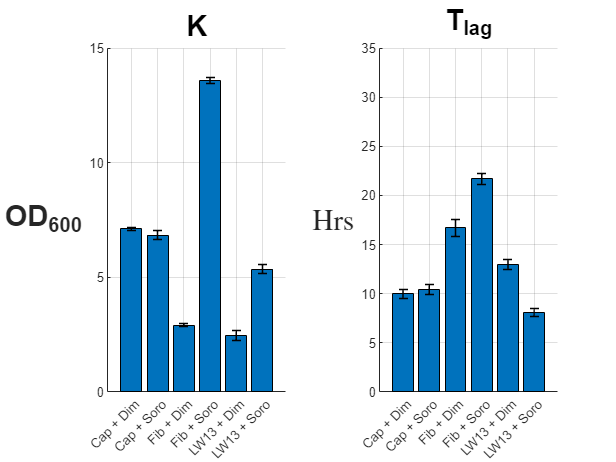

figure(); clf;
subplot(1,2,1)
hold on
b = bar(categorical(Coc_titles),mean(K_vals)'+mean(D_vals)');
errorbar(mean(K_vals) + mean(D_vals),std(K_vals),'LineStyle','none','Color','k','LineWidth',1);
hold off
ylabel('OD_{600}','FontSize',20,'FontWeight','bold','Rotation',0);
ylim([0,15]);
title('K','FontSize',20,'FontWeight','bold');
grid on

subplot(1,2,2)
hold on
bar(categorical(Coc_titles),mean(tLAG_vals));
errorbar(mean(tLAG_vals),std(tLAG_vals),'LineStyle','none','Color','k','LineWidth',1);
hold off
ylabel('Hrs','Interpreter','latex','FontSize',20,'FontWeight','bold','Rotation',0);
ylim([0,35]);
title('T_{lag}','FontSize',20,'FontWeight','bold');
grid on

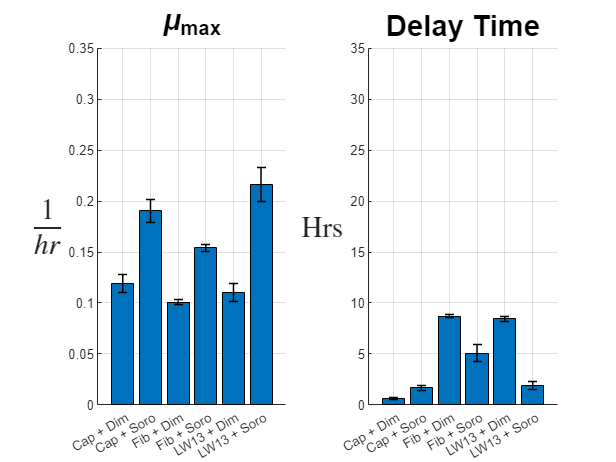


figure(); clf;
subplot(1,2,1)
hold on
b = bar(categorical(Coc_titles),mean(mu_max_vals));
errorbar(mean(mu_max_vals),std(mu_max_vals),'LineStyle','none','Color','k','LineWidth',1);
hold off
title('\mu_{max}','FontSize',20,'FontWeight','bold')
ylabel('$\frac{1}{hr}$','Interpreter','latex','FontSize',20,'FontWeight','bold','Rotation',0);
ylim([0,0.35]);
grid on

subplot(1,2,2)
hold on
b = bar(categorical(Coc_titles),mean(td_vals));
errorbar(mean(td_vals),std(td_vals),'LineStyle','none','Color','k','LineWidth',1);
hold off
title('Delay Time','FontSize',20,'FontWeight','bold')
ylabel('Hrs','Interpreter','latex','FontSize',20,'FontWeight','bold','Rotation',0);
ylim([0,35]);
grid on


figure(); clf;
subplot(1,2,1)
hold on
b = bar(categorical(Coc_titles),mean(mu_max_vals3));
errorbar(mean(mu_max_vals3),std(mu_max_vals3),'LineStyle','none','Color','k','LineWidth',1);
hold off
title('\mu_{max3}','FontSize',20,'FontWeight','bold')
ylabel('$\frac{1}{hr}$','Interpreter','latex','FontSize',20,'FontWeight','bold','Rotation',0);
ylim([0,0.3]);
grid on

disp(mean(mu_max_vals3));

    0.1107    0.1927    0.1491    0.1582    0.1978    0.1942



disp(std(mu_max_vals3));

    0.0078    0.0063    0.0008    0.0042    0.0157    0.0136



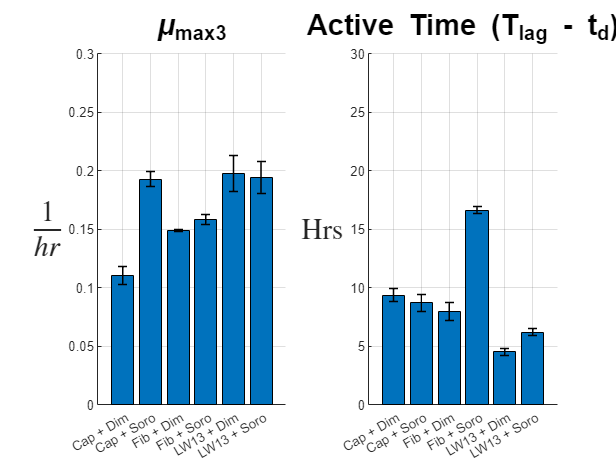


% Tlag - td shows time actively growing on AD %
subplot(1,2,2)
activeT = tLAG_vals - td_vals;
hold on
b = bar(categorical(Coc_titles),mean(activeT));
errorbar(mean(activeT),std(activeT),'LineStyle','none','Color','k','LineWidth',1);
hold off
title('Active Time (T_{lag} - t_{d})','FontSize',20,'FontWeight','bold')
ylabel('Hrs','Interpreter','latex','FontSize',20,'FontWeight','bold','Rotation',0);
ylim([0,30]);
grid on

### Cocultures (gDCW's)

Coc_titles = ["Cap + Dim";"Cap + Soro";"Fib + Dim";"Fib + Soro";"LW13 + Dim";"LW13 + Soro"];
Colors = {'k','k','r','r','b','b'};
Styles = {'-','--','-','--','-','--'};
Inits = {[4.4,0.1,2],[2.4,0.1,2],[1.4,0.1,20],[4.2,0.1,1],[1.4,0.1,1],[2.3,0.1,1]}; %Initials for solver!
Inits2 = {[0.1,1],[0.15,1],[0.10,10],[0.15,1],[0.1,10],[0.15,1]}; %Initials for exponential solver

% Make storage variables for later %
K_vals = zeros(3,length(Coc_titles));
D_vals = zeros(3,length(Coc_titles));
muR_vals = zeros(3,length(Coc_titles));
tLAG_vals = zeros(3,length(Coc_titles));
mu_max_vals = zeros(3,length(Photo_titles));
mu_max_vals3 = zeros(3,length(Photo_titles));
td_vals = zeros(3,length(Photo_titles));



for i = 1:size(all_coc_gDCW,1)
    gDCWs = all_coc_gDCW{i,2}*1000 - 0.345; %NOTE: These are backwards from Coculture OD's
    Times = all_coc_gDCW{i,1}; %NOTE: These are backwards from Coculture OD's
   
    % Plot the individual data sets with their Gompertz models
    x = Times;
    figure(); clf;
    for j = 1:3
        % Set up fitting parameters %
        Xo = gDCWs(1,j); %Initial biomass
        foB = fitoptions('Method','NonlinearLeastSquares','Lower',[0,0,0,0],'Upper',[5.0,0.3,25,Xo],'StartPoint',[Inits{i},Xo]);
        ft_ZMB = fittype('d + a*exp(-exp(exp(1)*b/a * (c - x) + 1))','independent',{'x'},'dependent',{'y'},'options',foB); %Zweitering
        % a = Carrying Capacity
        % b = Growth Rate
        % c = Delay Time
        % d = Vertical Shift

        % Define gDCW measurements and model predictions
        y = gDCWs(:,j);
        [curve_ZMB,~] = fit(x,y,ft_ZMB);
        subplot(1,3,j)
        plot(x,y,'ko',linspace(0,max(x),301),curve_ZMB(linspace(0,max(x),301)),'--')
        xlabel('Time Elapsed (hrs)')
        ylabel('[Biomass] (gDCW/L)')
        title([Coc_titles(i),' Sample #',num2str(j)])
        K_vals(j,i) = curve_ZMB.a;
        muR_vals(j,i) = curve_ZMB.b;
        tLAG_vals(j,i) = curve_ZMB.c;
        D_vals(j,i) = curve_ZMB.d;

        % Exponential Predictions from full Gompertz %
        tEXP = linspace(0,tLAG_vals(j,i),21); %21 points between start and Tlag
        % tEXP = Times(1:3); %First three points
        % fo2 = fitoptions('Method','NonlinearLeastSquares','Lower',[0,0],'Upper',[0.3,30],'StartPoint',Inits2{i});
        % ft_XM = fittype('Xo*exp(a*(t-b))','independent',{'t'},'dependent',{'y'},'problem',{'Xo'},'options',fo2); %Exponential Growth
        % [curve_XM,sXM] = fit(tEXP',curve_ZMB(tEXP),ft_XM,'problem',Xo);
        % [curve_XM,sXM] = fit(tEXP,y(1:3),ft_XM,'problem',Xo);
        fo2 = fitoptions('Method','NonlinearLeastSquares','Lower',[Xo,0,0],'Upper',[Xo*5,0.3,30],'StartPoint',[Xo,Inits2{i}]);
        ft_XMXo = fittype('Xo*exp(a*(t-b))','independent',{'t'},'dependent',{'y'},'options',fo2); %Exponential Growth
        [curve_XMXo,sXMXo] = fit(tEXP',curve_ZMB(tEXP),ft_XMXo);
        mu_max_vals(j,i) = curve_XMXo.a;
        td_vals(j,i) = curve_XMXo.b; 
        disp(strcat(Coc_titles(i) , ' Sample # ' , num2str(j) ,' has XMXo R^2 of ', num2str(sXMXo.adjrsquare)));

        % t_d values are reasonable, but the mu_max vals are off %
        % Try using time between t_d and Tlag to get mu_max %
        tEXP3 = linspace(mean([td_vals(j,i),tLAG_vals(j,i)]),tLAG_vals(j,i),21);
        fo3 = fitoptions('Method','NonlinearLeastSquares','Lower',[0,0,0],'Upper',[Xo*5,0.3,30],'StartPoint',[Xo,Inits2{i}]);
        ft_XMXo3 = fittype('Xo*exp(a*(t-b))','independent',{'t'},'dependent',{'y'},'options',fo3); %Exponential Growth
        [curve_XMXo3,sXMXo3] = fit(tEXP3',curve_ZMB(tEXP3),ft_XMXo3);
        disp(strcat(Coc_titles(i) , ' Sample # ' , num2str(j) ,' has XMXo3 R^2 of ', num2str(sXMXo3.adjrsquare)));
        mu_max_vals3(j,i) = curve_XMXo3.a;
    end
end 

### Plotting Coculture gDCW data

figure(); clf;
subplot(1,2,1)
hold on
b = bar(categorical(Coc_titles),mean(K_vals)'+mean(D_vals)');
errorbar(mean(K_vals) + mean(D_vals),std(K_vals),'LineStyle','none','Color','k','LineWidth',1);
hold off
ylabel('$\frac{gDCW}{L}$','Interpreter','latex','FontSize',20,'FontWeight','bold','Rotation',0);
ylim([0,5]);
title('K','FontSize',20,'FontWeight','bold');
grid on

subplot(1,2,2)
hold on
bar(categorical(Coc_titles),mean(tLAG_vals));
errorbar(mean(tLAG_vals),std(tLAG_vals),'LineStyle','none','Color','k','LineWidth',1);
hold off
ylabel('Hrs','Interpreter','latex','FontSize',20,'FontWeight','bold','Rotation',0);
ylim([0,35]);
title('T_{lag}','FontSize',20,'FontWeight','bold');
grid on

figure(); clf;
subplot(1,2,1)
hold on
b = bar(categorical(Coc_titles),mean(mu_max_vals));
errorbar(mean(mu_max_vals),std(mu_max_vals),'LineStyle','none','Color','k','LineWidth',1);
hold off
title('\mu_{max}','FontSize',20,'FontWeight','bold')
ylabel('$\frac{1}{hr}$','Interpreter','latex','FontSize',20,'FontWeight','bold','Rotation',0);
ylim([0,0.35]);
grid on

subplot(1,2,2)
hold on
b = bar(categorical(Coc_titles),mean(td_vals));
errorbar(mean(td_vals),std(td_vals),'LineStyle','none','Color','k','LineWidth',1);
hold off
title('Delay Time','FontSize',20,'FontWeight','bold')
ylabel('Hrs','Interpreter','latex','FontSize',20,'FontWeight','bold','Rotation',0);
ylim([0,35]);
grid on

figure(); clf;
subplot(1,2,1)
hold on
b = bar(categorical(Coc_titles),mean(mu_max_vals3));
errorbar(mean(mu_max_vals3),std(mu_max_vals3),'LineStyle','none','Color','k','LineWidth',1);
hold off
title('\mu_{max3}','FontSize',20,'FontWeight','bold')
ylabel('$\frac{1}{hr}$','Interpreter','latex','FontSize',20,'FontWeight','bold','Rotation',0);
ylim([0,0.3]);
grid on

disp(mean(mu_max_vals3));
disp(std(mu_max_vals3));

% Tlag - td shows time actively growing on AD %
subplot(1,2,2)
activeT = tLAG_vals - td_vals;
hold on
b = bar(categorical(Coc_titles),mean(activeT));
errorbar(mean(activeT),std(activeT),'LineStyle','none','Color','k','LineWidth',1);
hold off
title('Active Time (T_{lag} - t_{d})','FontSize',20,'FontWeight','bold')
ylabel('Hrs','Interpreter','latex','FontSize',20,'FontWeight','bold','Rotation',0);
ylim([0,30]);
grid on